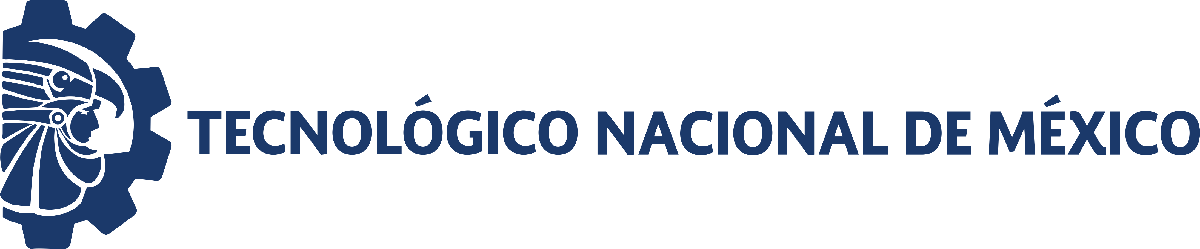                                 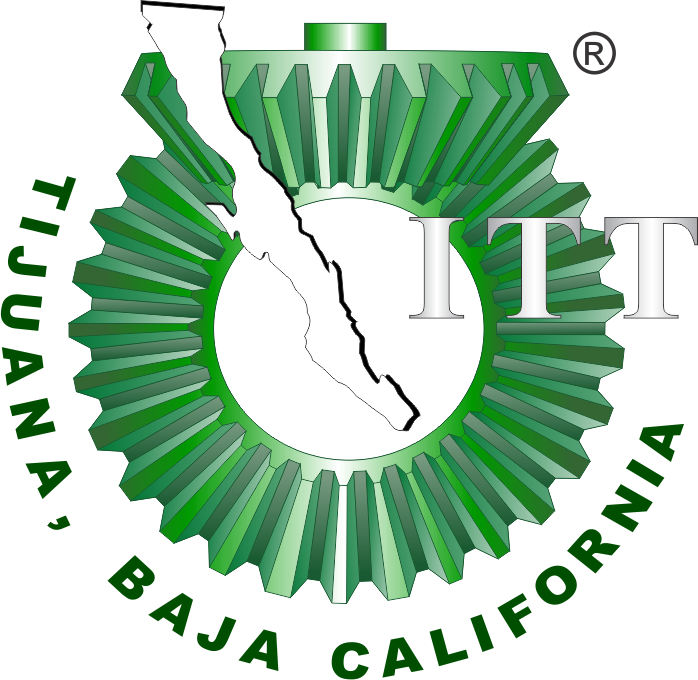

# Práctica 2: Sistema Respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: Miroslava Jacobo Mendoza

Número de control: 21212669

Correo institucional: l21212669**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "30";
file = "sysp2";
open_system (file);
parameters.StopTime = tend;
parameters.Solver = "ode15s";
parameters.MaxStep = "1E-3";
Controlador = "PID";

## Rendimiento del controlador

kP = 202.0334

kI = 3709.0206

kD = 1.0047

Settling time = 0.0998 seconds

Overshoot = 7.02%

Peak = 1.07

## Respuesta al escalón

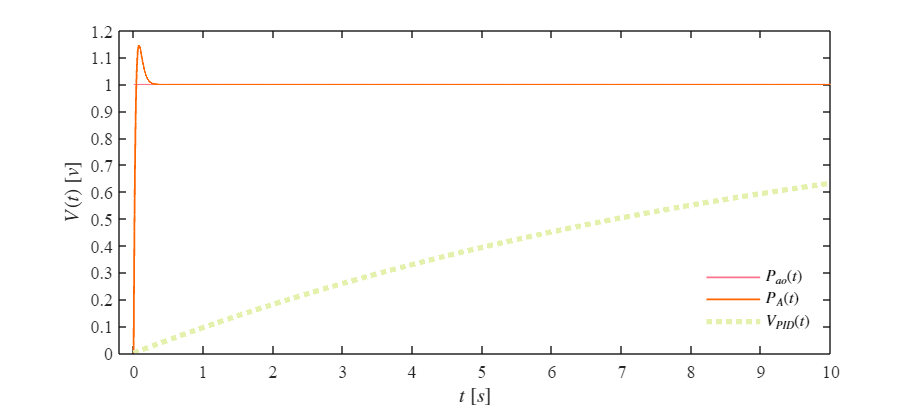

Signal = 'Escalon';
set_param('sysp0/S1', 'sw', '1');
set_param('sysp0/Pao(t)', 'sw', '1');

x1 = sim(file, parameters);
plotsignals (x1.t, x1.Pao, x1.VPID, x1.PA, Signal)

## Respuesta al impulso

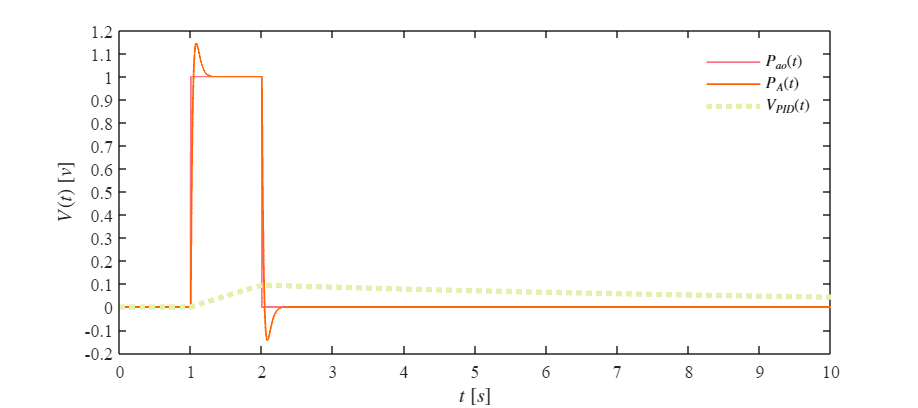

Signal = 'Impulso';
set_param('sysp0/S1', 'sw', '0');
set_param('sysp0/Pao(t)', 'sw', '1');

x2 = sim(file, parameters);
plotsignals (x2.t, x2.Pao, x2.VPID, x2.PA, Signal)

## Respuesta a la rampa

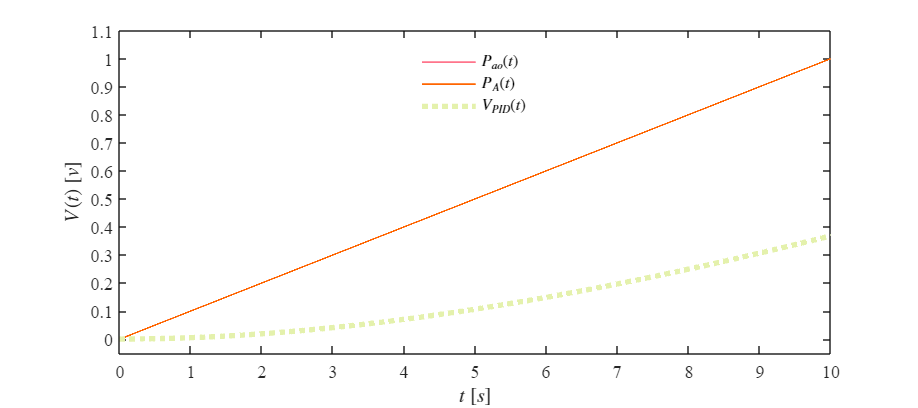

Signal = 'Rampa';
set_param('sysp0/S2', 'sw', '1');
set_param('sysp0/Pao(t)', 'sw', '0');

x3 = sim(file, parameters);
plotsignals (x3.t, x3.Pao, x3.VPID, x3.PA, Signal)

## Respuesta a la función sinusoidal

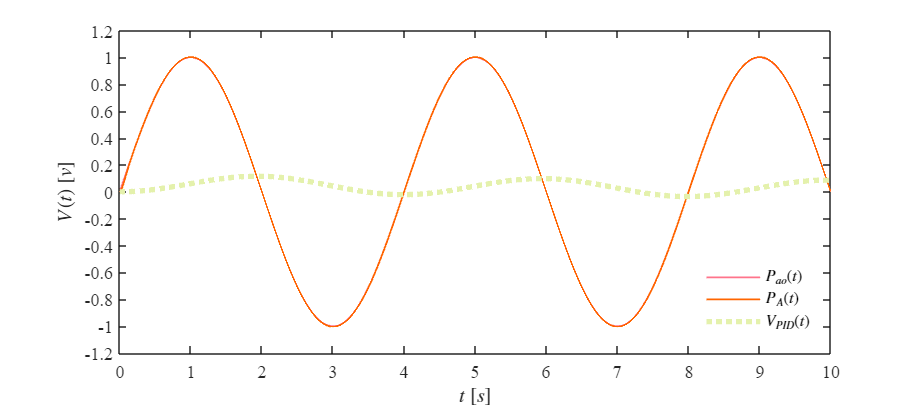

Signal = 'Sinusoidal';
set_param('sysp0/S2', 'sw', '0');
set_param('sysp0/Pao(t)', 'sw', '0');

x4 = sim(file, parameters);
plotsignals (x4.t, x4.Pao, x4.VPID, x4.PA, Signal)

## Funcion: Respuesta a las senales

function plotsignals(t,Ve,Vs,VPID,Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10,'points')
    
    rosa =[255/255, 116/255, 139/255];
    naranja =[255/255, 101/255, 0/255];
    verde =[228/255, 241/255, 172/255];
    hold on; grid off, box on;

    plot (t, Ve, 'LineWidth', 1, 'Color', rosa)
    plot (t, Vs, 'LineWidth', 1, 'Color', naranja)
    plot (t, VPID, ':', 'LineWidth', 3, 'Color', verde)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$V(t)$ $[v]$', 'Interpreter', 'Latex')



    L = legend('$P_{ao}(t)$',  '$P_A(t)$', '$V_{PID}(t)$');
    set(L, 'Interpreter', 'Latex', 'Location','Best', 'Box', 'Off')
    
    if Signal == "Escalon"
        xlim([-0.2, 10]); xticks (0:1:10) 
        ylim([0, 1.2]); yticks (0:0.1:1.2)
    
    elseif Signal == "Impulso"
        xlim([0, 10]); xticks (0:1:10)
        ylim([-0.2, 1.2]); yticks (-0.2:0.1:1.2)

    elseif Signal == "Rampa"
        xlim([0, 10]); xticks (0:1:10)
        ylim([-0.05, 1.1]); yticks (0:0.1:1.1)

    elseif Signal == "Sinusoidal"
        xlim ([0, 10]); xticks (0:1:10)
        ylim ([-1.2, 1.2]); yticks (-1.2:0.2:1.2)
    end
    exportgraphics (gcf, [Signal,'.pdf'], 'ContentType', 'Vector')
end